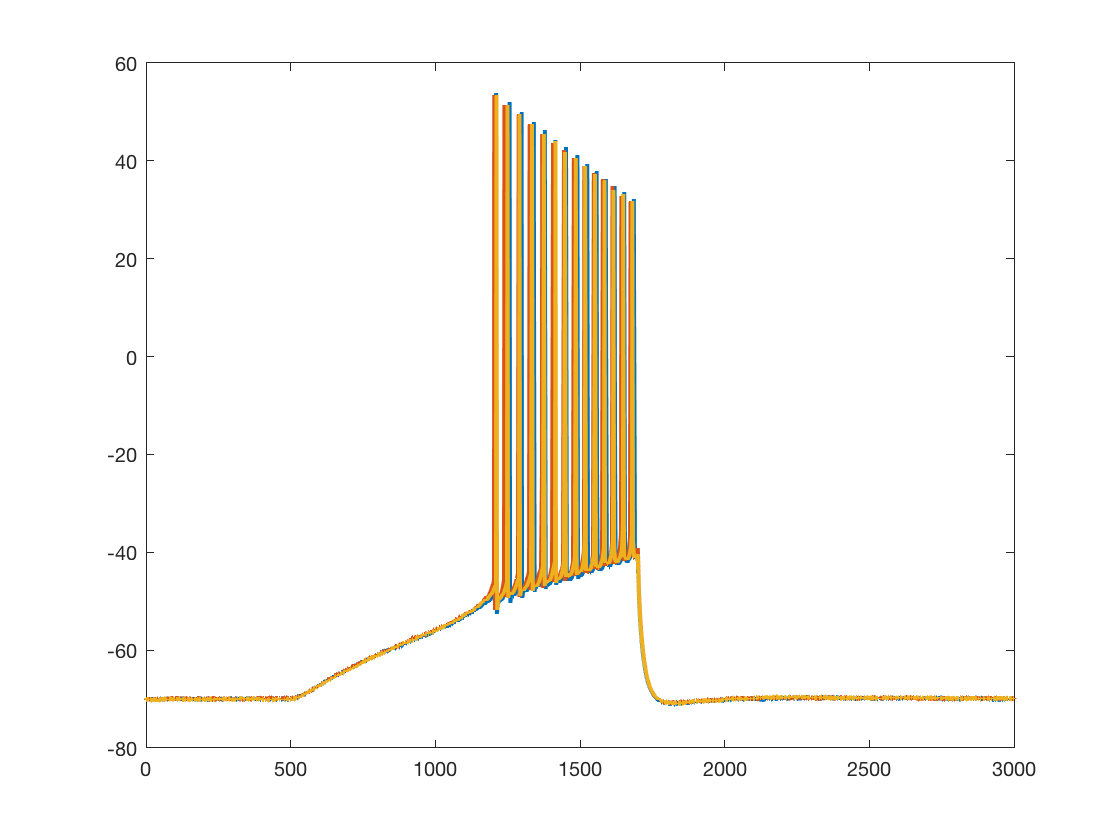


% phase-plane plots to measure AP threshold, etc. 

t = c001_Time*1000;

in = [c002_Membrane_Voltage_1; c003_Membrane_Voltage_1; c004_Membrane_Voltage_1]*1000;
%in = [c002_Membrane_Voltage_2; c003_Membrane_Voltage_2; c004_Membrane_Voltage_2]*1000;
%in = [c002_Membrane_Voltage_1; c002_Membrane_Voltage_1; c002_Membrane_Voltage_1]*1000;



% create the command variable with a smooth range from 0 to 1 nA

cmd = zeros(1,60000);



% for 1000 pA ramp
cmd(1,10000:34000) = (0:(1e-9/24000):1e-9);

% for CA1 or CA3, etc. 500 pA ramp
%cmd(1,10000:34000) = ((0:(1e-9/24000):1e-9))/2;

    
    

figure;
plot(t,in,'LineWidth',2);

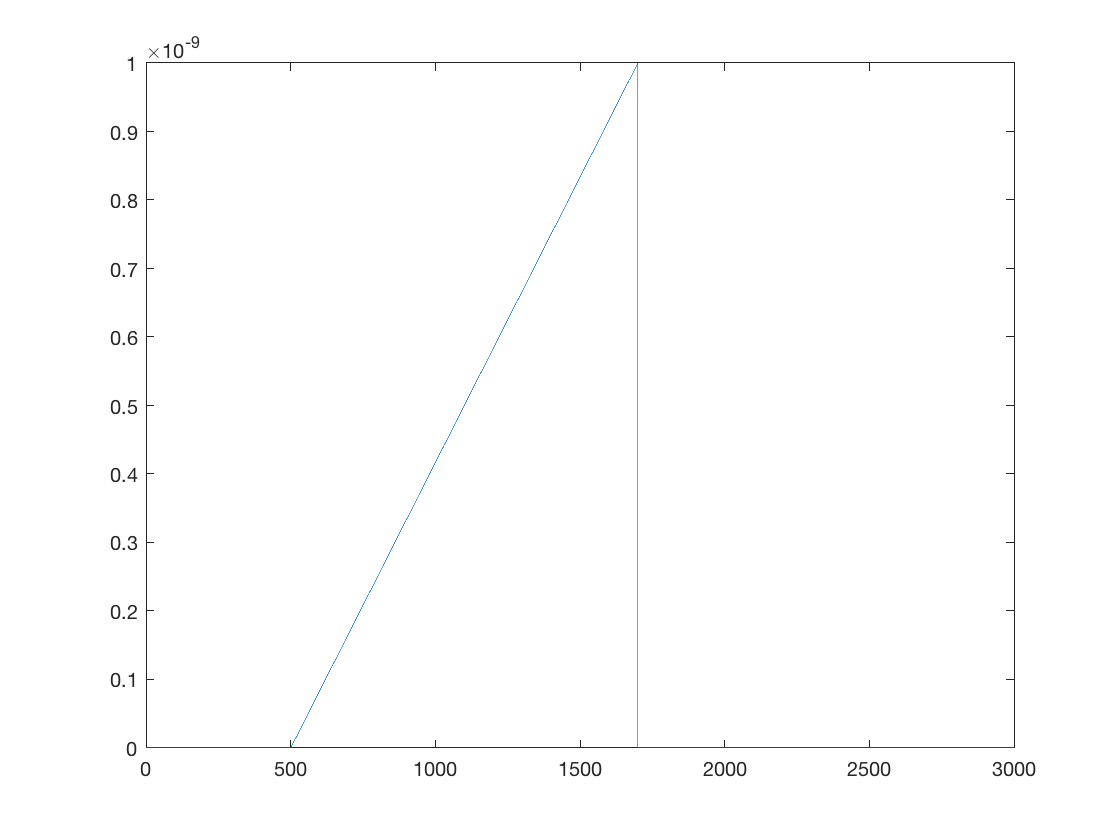

%ylim([-80 -20]);
%xlim([500 1500]);


figure;
%plot(t,cmd);
plot(t(1:60000),cmd);   % if the recording uses the old format, partial t

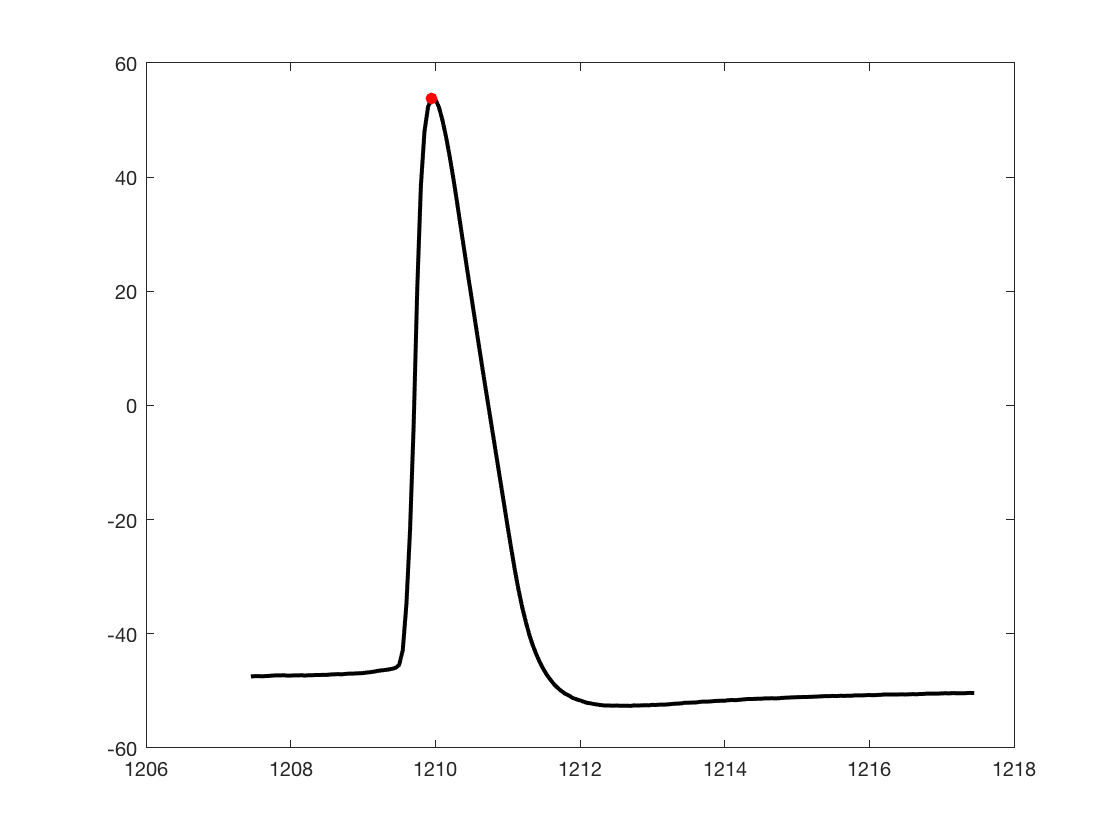




%% SPIKE find

ii = 0;
k= 1;

while ii == 0
    
    [PKS,LOCS] = findpeaks(in(k,:),'MinPeakHeight',-10,'MinPeakDistance',0.2);
    
    if LOCS > 0
        spikeindex_pp = LOCS(1);   %_pp means phase plane
        peak_t = t(LOCS(1));
        t_range = (spikeindex_pp-50):1:(spikeindex_pp+150);
        in_pp = in(k,t_range);
        t_pp = t(t_range);
        cmd_pp = cmd(t_range);
        
        ii = 1;
        
    else
        
        k = k+1;
        
    end        
end

figure;
plot(t_pp,in_pp,"LineWidth",2,"color",'k');
hold on
plot(t(LOCS(1)),PKS(1),'o','MarkerEdgeColor','none','MarkerFaceColor','r')

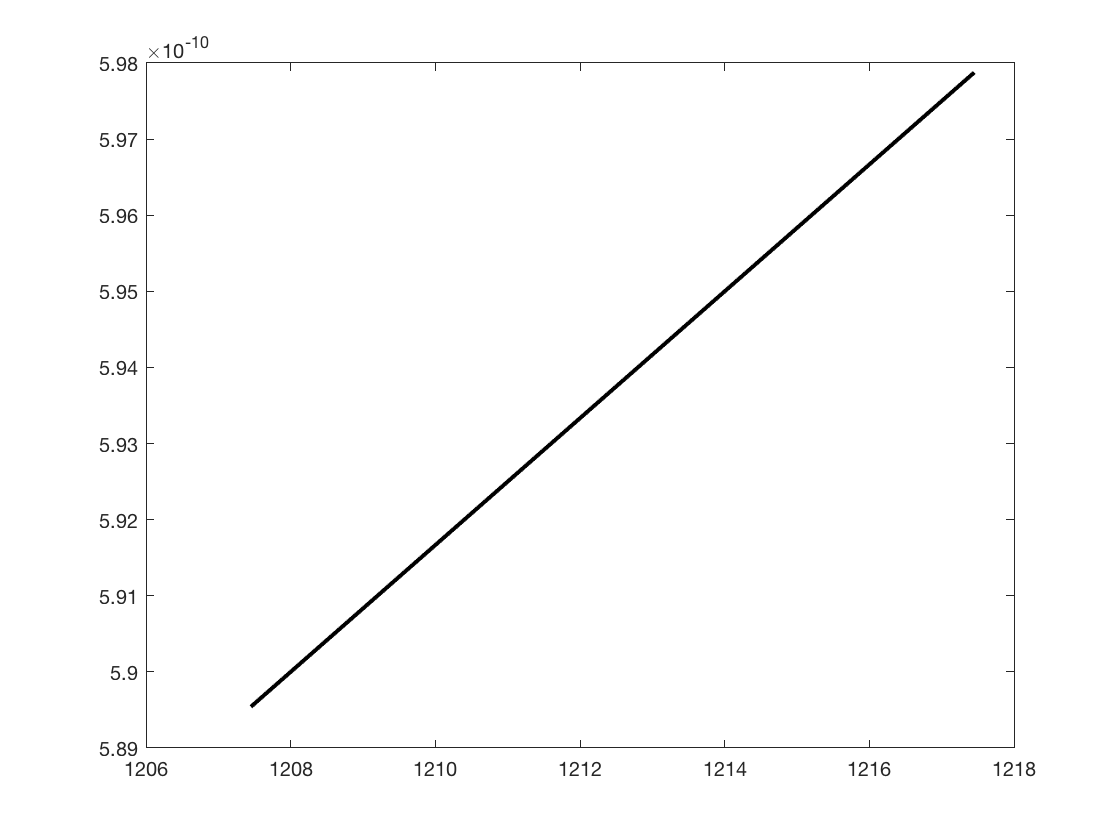

figure;
plot(t_pp,cmd_pp,"LineWidth",2,"color",'k');

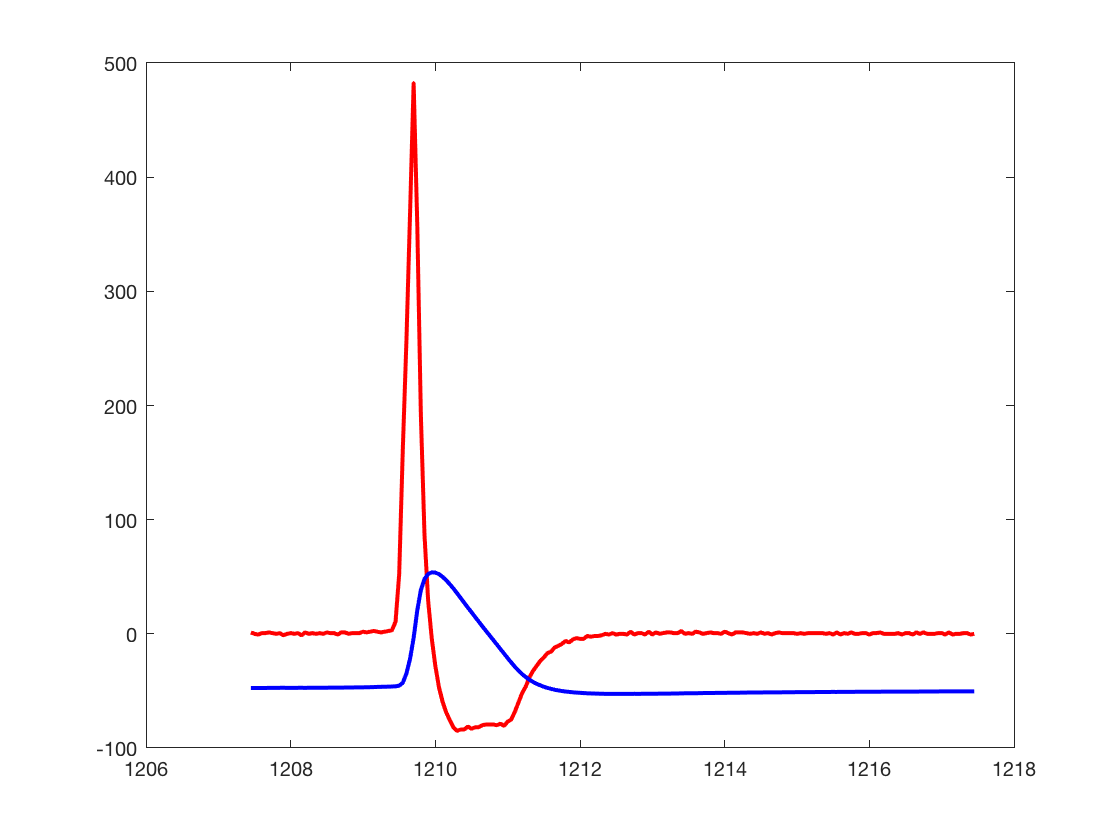



%% Phase-Plane, AP threshold, other measures

in_pp_d = diff(in_pp)*20; %50us sampling interval - factor 20 corrects for that
in_pp_d(end+1) = 0;


figure;
plot(t_pp,in_pp_d,'LineWidth',2,'Color','r')
hold on
plot(t_pp,in_pp,'LineWidth',2,'Color','b')

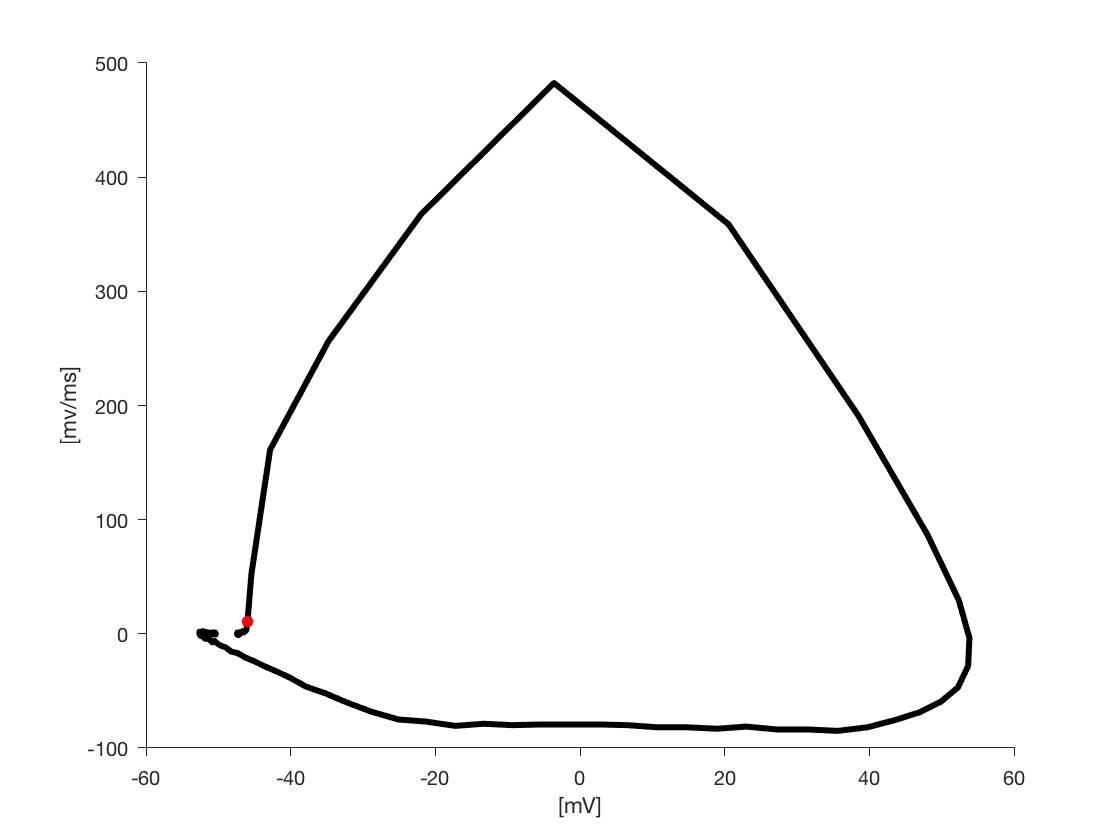


fig1 = figure;
plot(in_pp,in_pp_d,'LineWidth',3,'Color',[0 0 0])
hold on

k = 1;
while in_pp_d(k) < 50
    if in_pp_d(k) > 5 & in_pp_d(k) < in_pp_d(k+1)
        AP_th = round(in_pp(k),2);
        AP_th_t = t_pp(k);
        start_t = k;                                % this step creates the start point for the interpolant              
        rheobase = round((cmd_pp(k)*1E12),4);
        afterhyp = (min(in_pp) - AP_th);
        break
    end
k = k+1;
end

plot(in_pp(k),in_pp_d(k),'o','MarkerEdgeColor','none','MarkerFaceColor','r');
set(gca,'box','off','color','none','TickDir','out')
xlabel('[mV]') 
ylabel('[mv/ms]')



% this step uses the afterhyperpolarization negative peak to establish the
% end point for the interpolant

neg_peak = min(in_pp);                          

g=1;

for g=1:length(in_pp)
    if in_pp(g) == neg_peak
        min_t = t_pp(g);
        end_t = mean(g);
    else g = g+1;
    end
end

% AP amplitude is the difference from the threshold Vm to the peak Vm, and
% the half-amplitude is the halfway Vm between the two

spikeamp = max(in_pp)-AP_th

spikeamp = 99.8138

halfamp_Vm = AP_th+(spikeamp/2)

halfamp_Vm = 3.9369



% creat the gridded interpolant of the spike waveform in between the
% threshold and the AHP neg peak
% use the interpolant to measure the half-width more accurately

x = t_pp(start_t:end_t);
y = in_pp(start_t:end_t);

F = griddedInterpolant(x,y);

w = linspace(t_pp(start_t),t_pp(end_t),10000);
v = F(w);



q = find(v>halfamp_Vm);

z = min(q);
zz = max(q);
v(z);
w(z);
w(zz);
halfwidth = w(zz)-w(z)

halfwidth = 0.9673

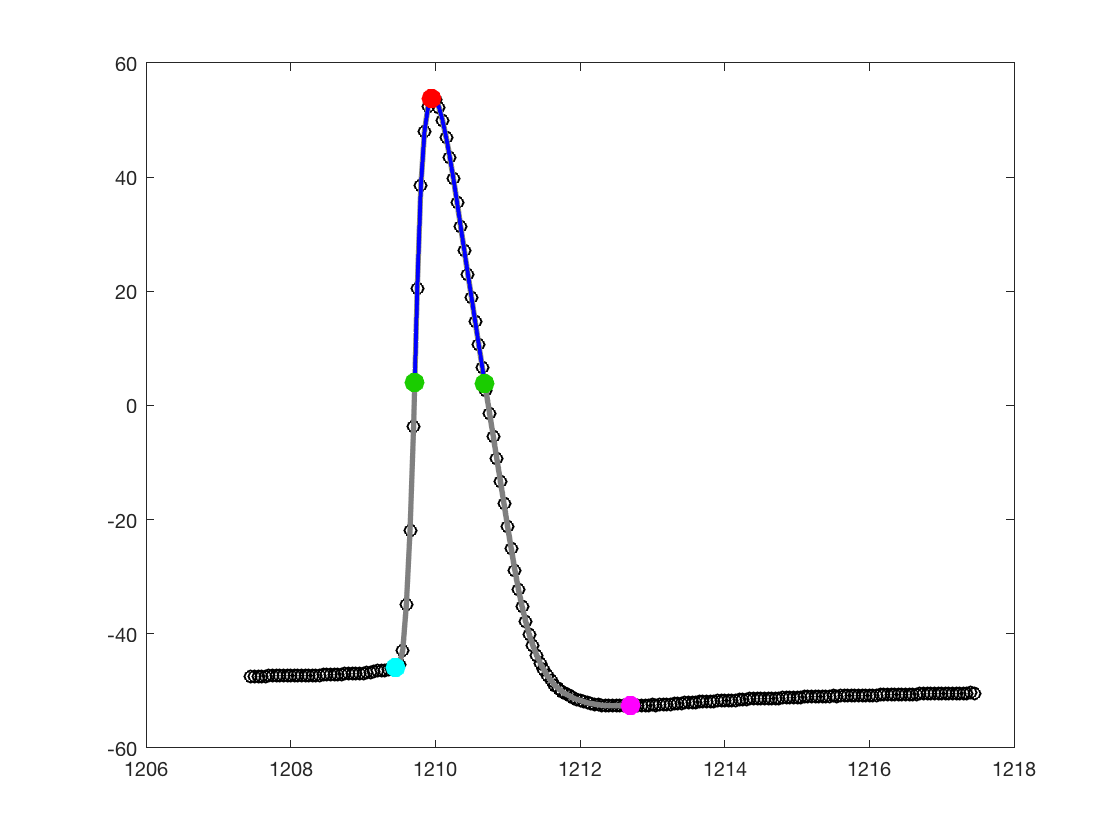




% create a figure showing the spike waveform, interpolant, and measured
% points


figure_1 = figure;
plot(t_pp,in_pp,'ko');
hold on
plot(w,v,'.','color',[0.5 0.5 0.5])
plot(w(z:zz),v(z:zz),'Color','b','lineWidth',2)
plot(w(z),v(z),'o','MarkerEdgeColor','none','MarkerFaceColor',[0.1 0.8 0],"MarkerSize",10)
plot(w(zz),v(zz),'o','MarkerEdgeColor','none','MarkerFaceColor',[0.1 0.8 0],"MarkerSize",10)
plot(t(LOCS(1)),PKS(1),'o','MarkerEdgeColor','none','MarkerFaceColor','r',"MarkerSize",10)
plot(AP_th_t,AP_th,'o','MarkerEdgeColor','none','MarkerFaceColor','c',"MarkerSize",10)
plot(min_t,neg_peak,'o','MarkerEdgeColor','none','MarkerFaceColor','m',"MarkerSize",10)



clear w v x y q

% output values for traces 1


spikeamp

spikeamp = 99.8138

halfwidth

halfwidth = 0.9673

maxrate = max(in_pp_d)

maxrate = 482.5000

minrate = min(in_pp_d)

minrate = -85.0000

afterhyp

afterhyp = -6.6550

AP_th

AP_th = -45.9700

rheobase

rheobase = 591.2083

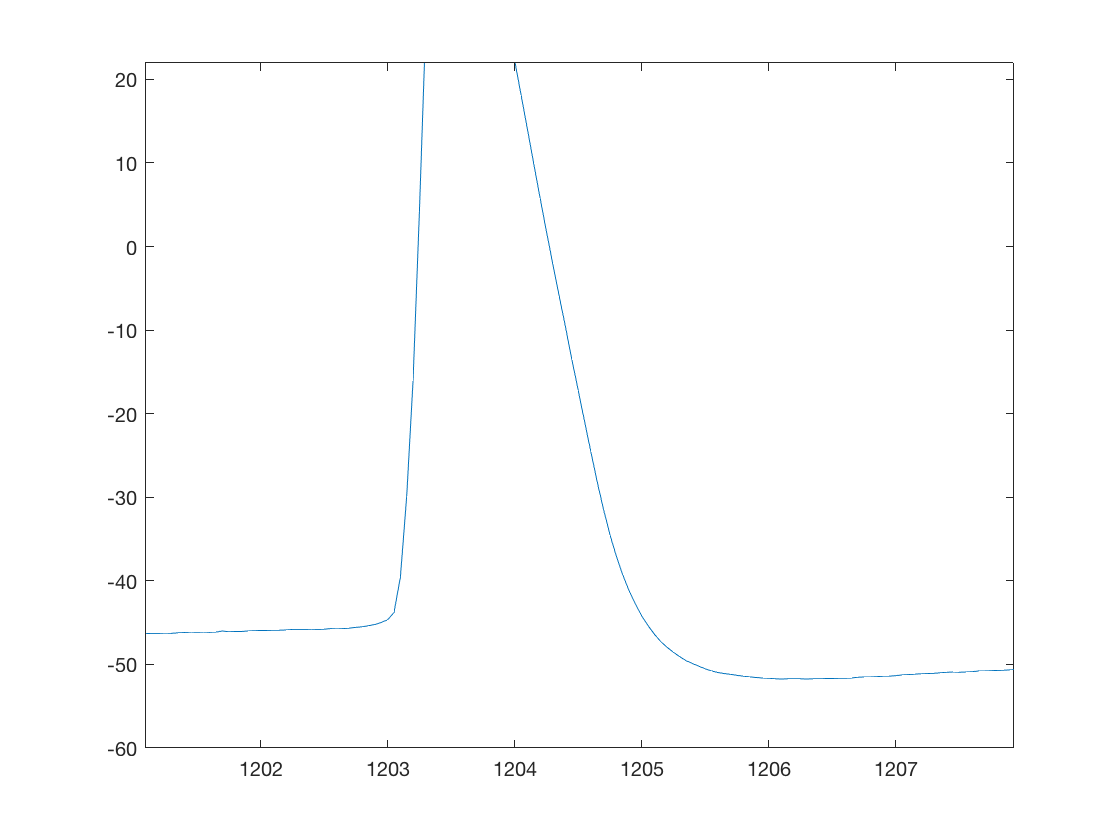


% repeat with second sweep

ii = 0;
k= 2;

while ii == 0
    
    [PKS_2,LOCS] = findpeaks(in(k,:),'MinPeakHeight',-10,'MinPeakDistance',0.2);
    
    if LOCS > 0
        spikeindex_pp = LOCS(1);   %_pp means phase plane
        peak_t = t(LOCS(1));
        t_range_2 = (spikeindex_pp-50):1:(spikeindex_pp+150);
        in_pp_2 = in(k,t_range_2);
        t_pp_2 = t(t_range_2);
        cmd_pp_2 = cmd(t_range_2);

        ii = 1;
        
    else
        
        k = k+1;
        
     end        
end


figure;
plot(t_pp_2,in_pp_2);

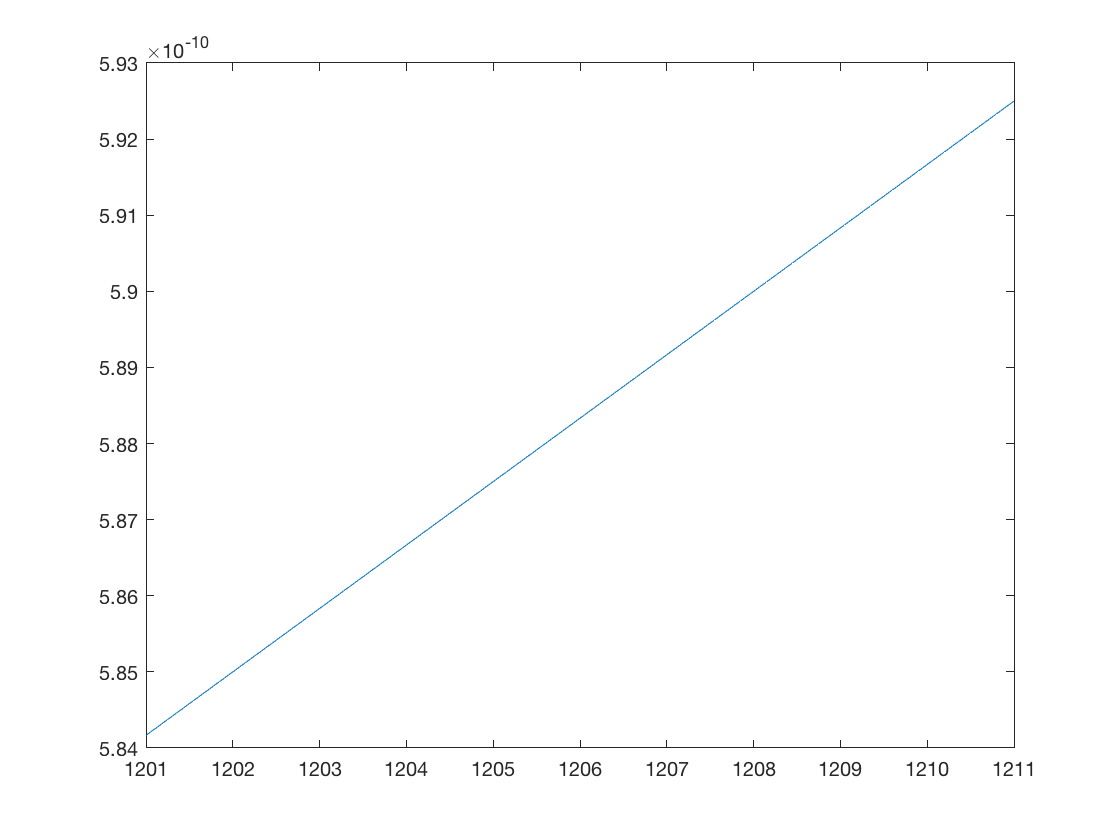

figure;
plot(t_pp_2,cmd_pp_2);

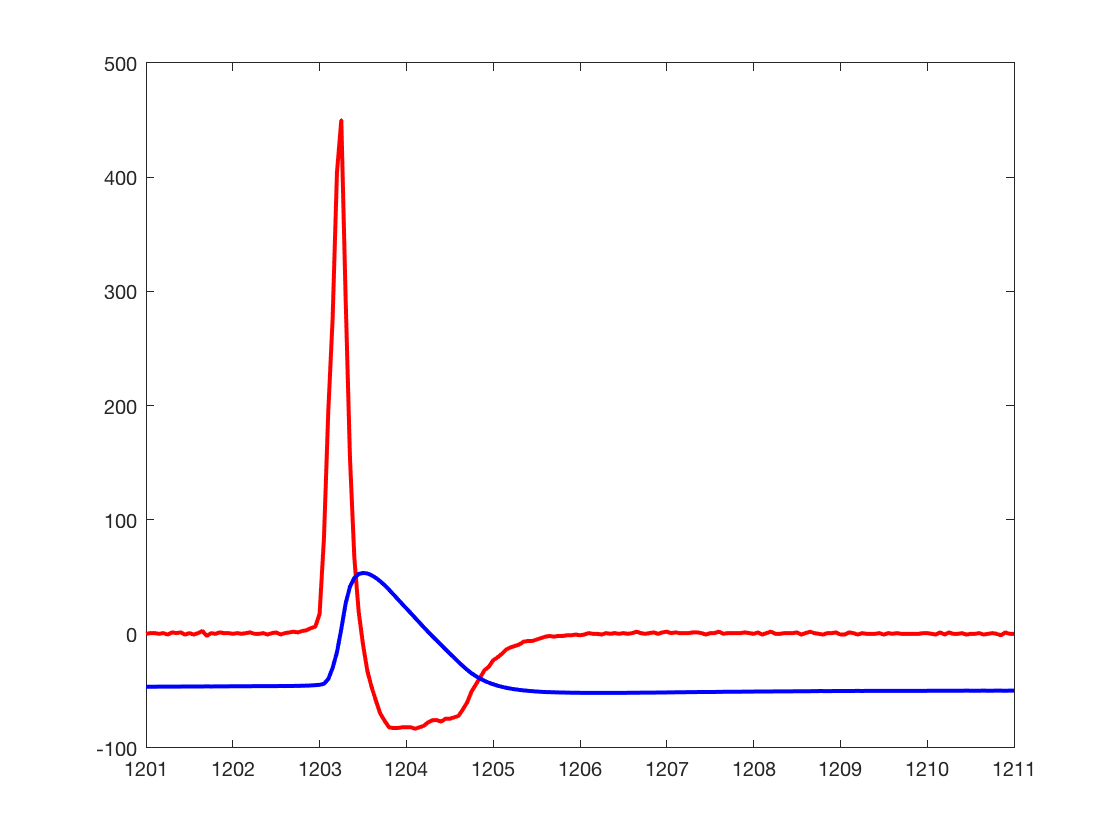


%% Phase-Plane, AP threshold

in_pp_d_2 = diff(in_pp_2)*20; %50us sampling interval - factor 20 corrects for that
in_pp_d_2(end+1) = 0;


figure;
plot(t_pp_2,in_pp_d_2,'LineWidth',2,'Color','r')
hold on
plot(t_pp_2,in_pp_2,'LineWidth',2,'Color','b')

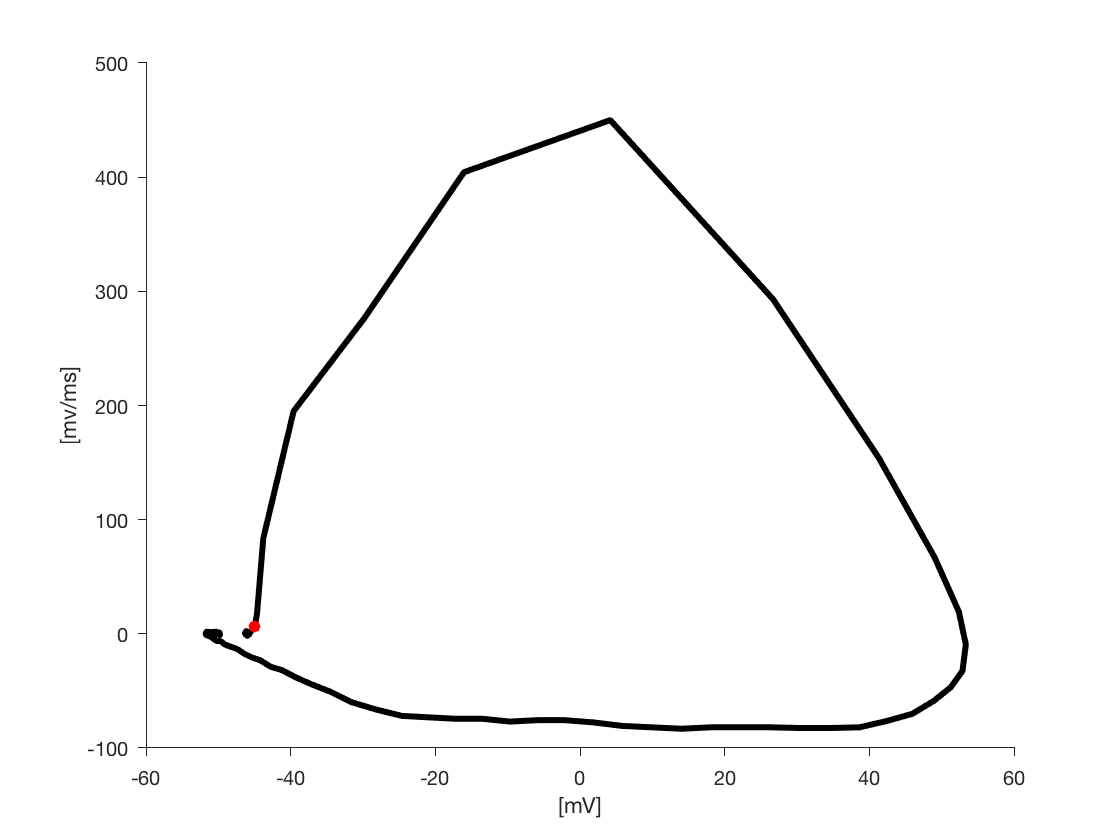


figure;
plot(in_pp_2,in_pp_d_2,'LineWidth',3,'Color',[0 0 0])
hold on

k = 1;
while in_pp_d_2(k) < 50
    if in_pp_d_2(k) > 5 & in_pp_d_2(k) < in_pp_d_2(k+1)
        AP_th_2 = round(in_pp_2(k),2);
        AP_th_t_2 = t_pp_2(k);
        start_t = k;                                % this step creates the start point for the interpolant   
        rheobase_2 = round((cmd_pp_2(k)*1E12),4);
        afterhyp_2 = (min(in_pp_2) - AP_th_2);

        break
    end
k = k+1;
end

plot(in_pp_2(k),in_pp_d_2(k),'o','MarkerEdgeColor','none','MarkerFaceColor','r');
set(gca,'box','off','color','none','TickDir','out')
xlabel('[mV]') 
ylabel('[mv/ms]')

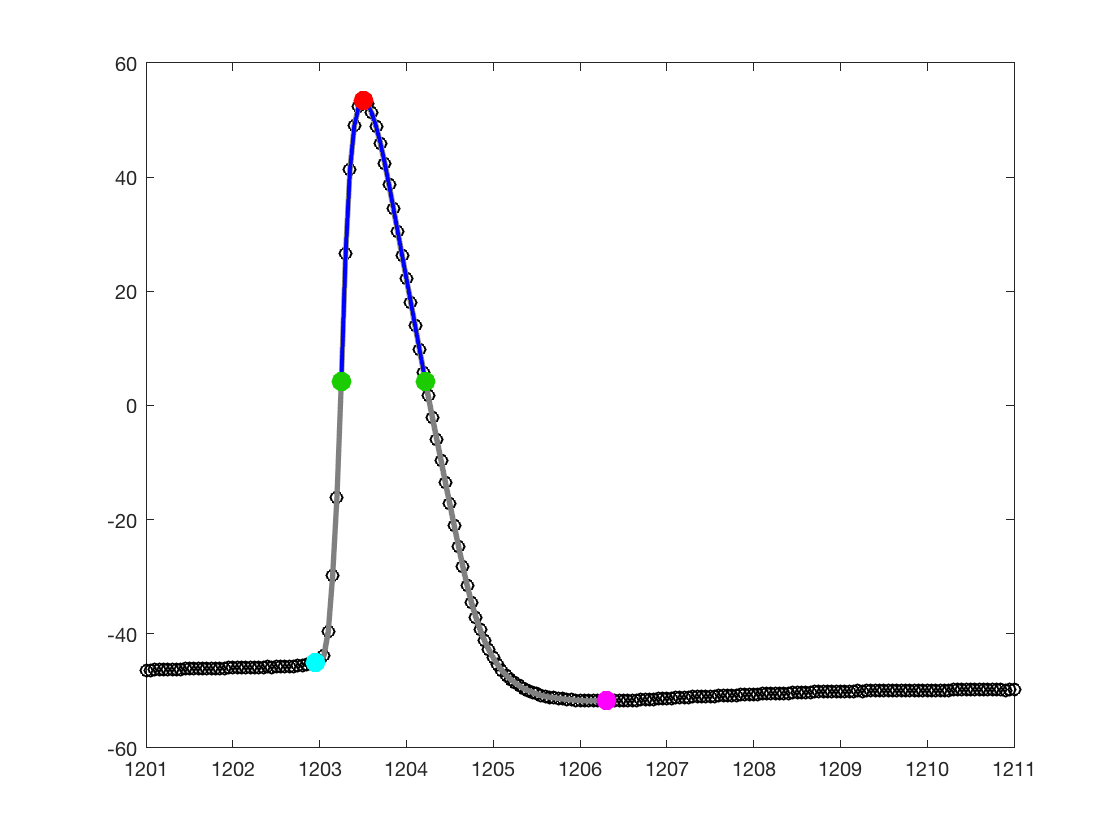





% this step uses the afterhyperpolarization negative peak to establish the
% end point for the interpolant

neg_peak = min(in_pp_2);                          

g=1;

for g=1:length(in_pp_2)
    if in_pp_2(g) == neg_peak
        min_t = t_pp_2(g);
        end_t = mean(g);
    else g = g+1;
    end
end

% AP amplitude is the difference from the threshold Vm to the peak Vm, and
% the half-amplitude is the halfway Vm between the two

spikeamp_2 = max(in_pp_2)-AP_th_2;
halfamp_Vm_2 = AP_th_2+(spikeamp_2/2);

% creat the gridded interpolant of the spike waveform in between the
% threshold and the AHP neg peak
% use the interpolant to measure the half-width more accurately

x = t_pp_2(start_t:end_t);
y = in_pp_2(start_t:end_t);

F = griddedInterpolant(x,y);

w = linspace(t_pp_2(start_t),t_pp_2(end_t),25000);
v = F(w);



q = find(v>halfamp_Vm_2);

z = min(q);
zz = max(q);
v(z);
w(z);
w(zz);
halfwidth_2 = w(zz)-w(z);



% create a figure showing the spike waveform, interpolant, and measured
% points


figure;
plot(t_pp_2,in_pp_2,'ko');
hold on
plot(w,v,'.','color',[0.5 0.5 0.5])
plot(w(z:zz),v(z:zz),'Color','b','lineWidth',2)
plot(w(z),v(z),'o','MarkerEdgeColor','none','MarkerFaceColor',[0.1 0.8 0],"MarkerSize",10)
plot(w(zz),v(zz),'o','MarkerEdgeColor','none','MarkerFaceColor',[0.1 0.8 0],"MarkerSize",10)
plot(t(LOCS(1)),PKS_2(1),'o','MarkerEdgeColor','none','MarkerFaceColor','r',"MarkerSize",10)
plot(AP_th_t_2,AP_th_2,'o','MarkerEdgeColor','none','MarkerFaceColor','c',"MarkerSize",10)
plot(min_t,neg_peak,'o','MarkerEdgeColor','none','MarkerFaceColor','m',"MarkerSize",10)



clear w v x y 

% output values for traces 2


spikeamp_2

spikeamp_2 = 98.3138

halfwidth_2

halfwidth_2 = 0.9697

maxrate = max(in_pp_d_2)

maxrate = 450

minrate = min(in_pp_d_2)

minrate = -83.1250

afterhyp_2

afterhyp_2 = -6.7800

AP_th_2

AP_th_2 = -44.9700

rheobase_2

rheobase_2 = 585.7917

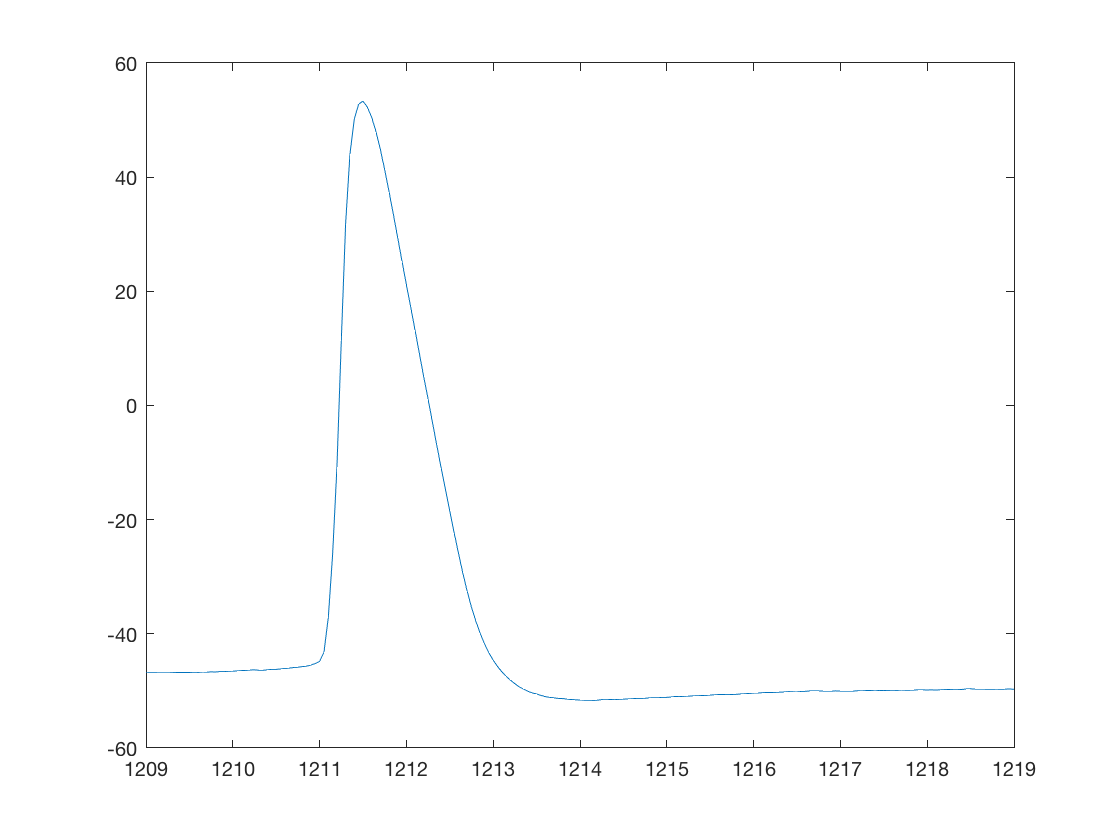


% repeat with third sweep

ii = 0;
k= 3;

while ii == 0
    
    [PKS_3,LOCS] = findpeaks(in(k,:),'MinPeakHeight',-10,'MinPeakDistance',0.2);
    
    if LOCS > 0
        spikeindex_pp = LOCS(1);   %_pp means phase plane
        peak_t = t(LOCS(1));
        t_range_3 = (spikeindex_pp-50):1:(spikeindex_pp+150);
        in_pp_3 = in(k,t_range_3);
        t_pp_3 = t(t_range_3);
        cmd_pp_3 = cmd(t_range_3);

        ii = 1;
        
    else
        
        k = k+1;
        
     end        
end

figure;
plot(t_pp_3,in_pp_3);

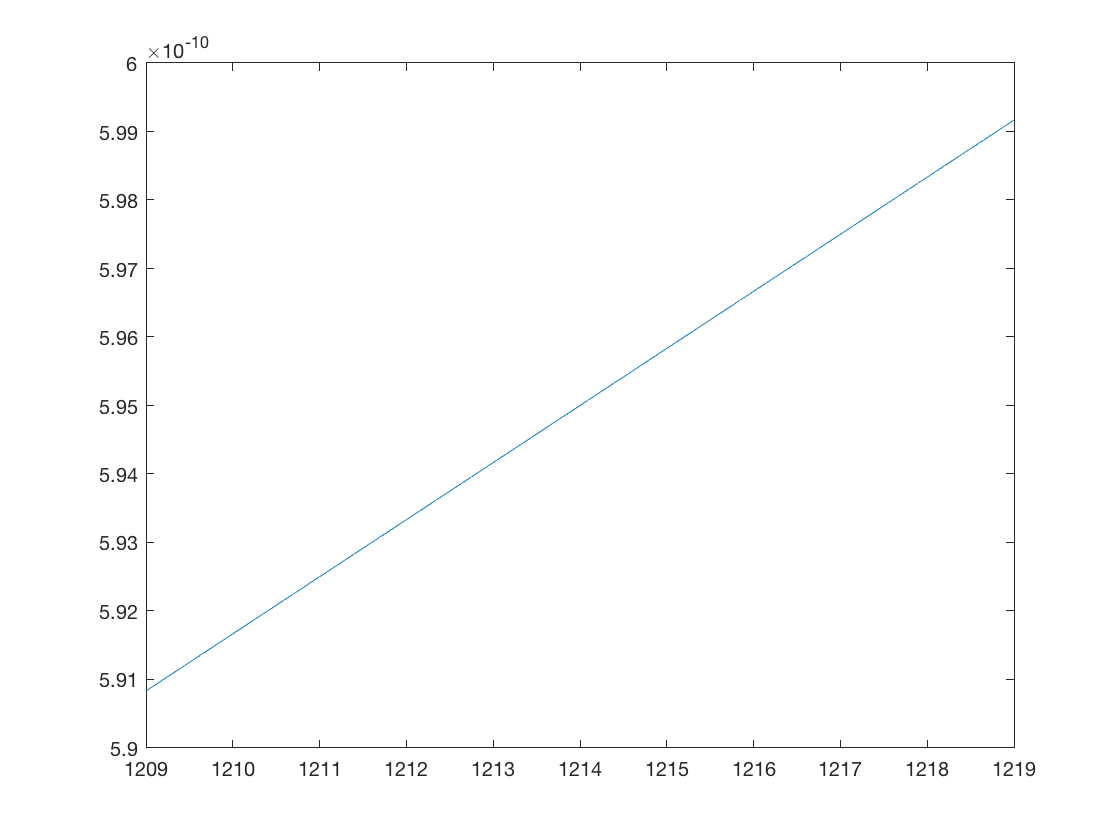

figure;
plot(t_pp_3,cmd_pp_3);

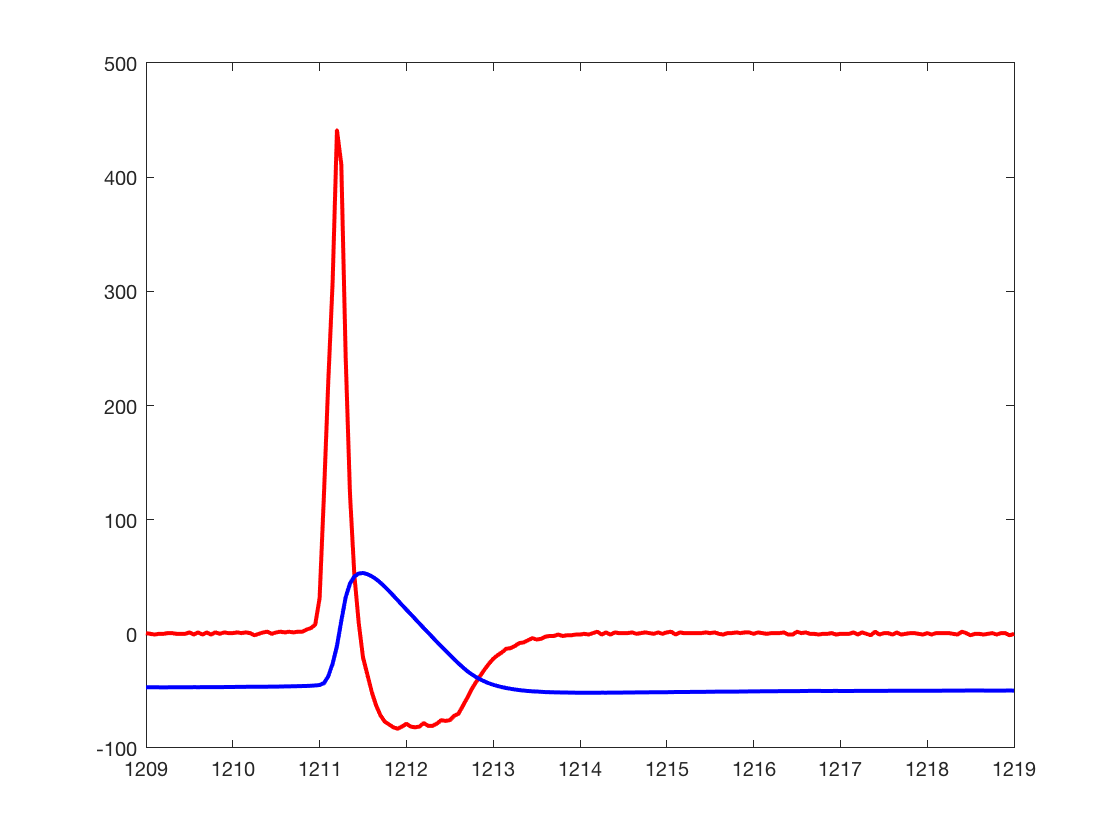


%% Phase-Plane, AP threshold

in_pp_d_3 = diff(in_pp_3)*20; %50us sampling interval - factor 20 corrects for that
in_pp_d_3(end+1) = 0;


figure;
plot(t_pp_3,in_pp_d_3,'LineWidth',2,'Color','r')
hold on
plot(t_pp_3,in_pp_3,'LineWidth',2,'Color','b')

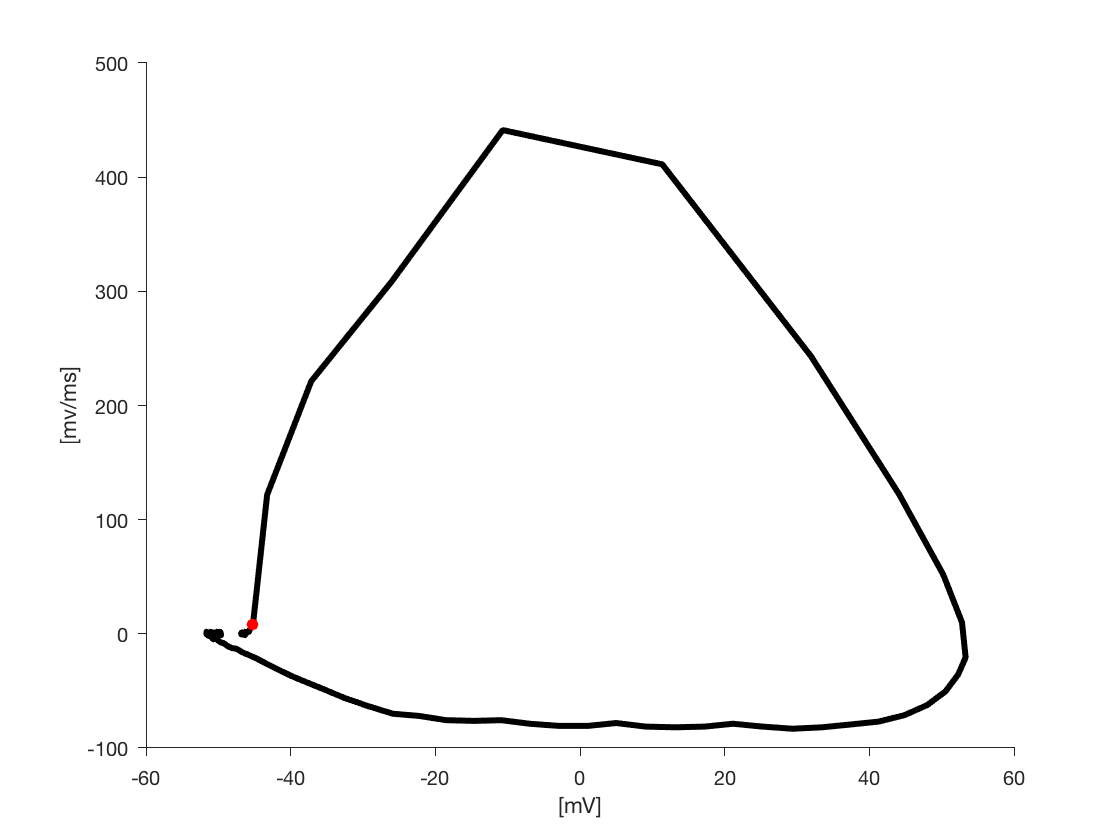


figure;
plot(in_pp_3,in_pp_d_3,'LineWidth',3,'Color',[0 0 0])
hold on

k = 1;
while in_pp_d_3(k) < 50
    if in_pp_d_3(k) > 5 & in_pp_d_3(k) < in_pp_d_3(k+1)
        AP_th_3 = round(in_pp_3(k),2);
        AP_th_t_3 = t_pp_3(k);
        start_t = k;
        rheobase_3 = round((cmd_pp_3(k)*1E12),4);
        afterhyp_3 = (min(in_pp_3) - AP_th_3);
        break
    end
k = k+1;
end



plot(in_pp_3(k),in_pp_d_3(k),'o','MarkerEdgeColor','none','MarkerFaceColor','r');
set(gca,'box','off','color','none','TickDir','out')
xlabel('[mV]') 
ylabel('[mv/ms]')

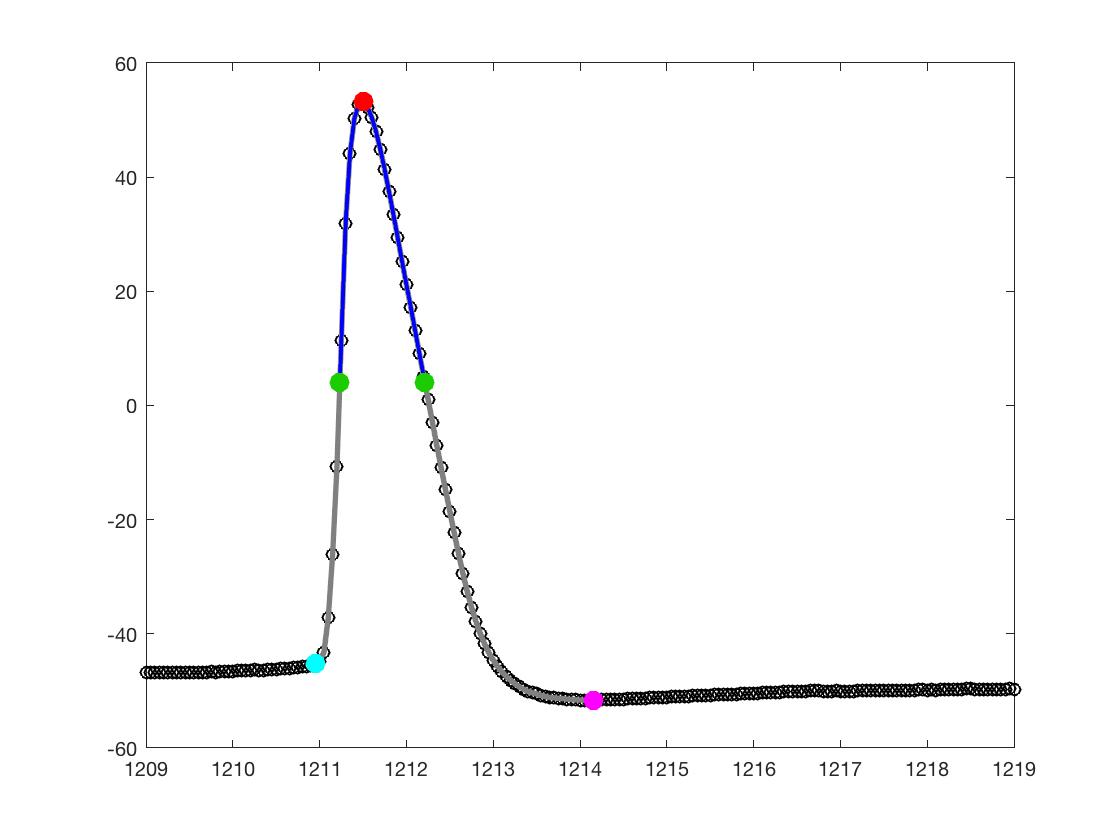




% this step uses the afterhyperpolarization negative peak to establish the
% end point for the interpolant

neg_peak = min(in_pp_3);                          

g=1;

for g=1:length(in_pp_3)
    if in_pp_3(g) == neg_peak
        min_t = t_pp_3(g);
        end_t = mean(g);
    else g = g+1;
    end
end

% AP amplitude is the difference from the threshold Vm to the peak Vm, and
% the half-amplitude is the halfway Vm between the two

spikeamp_3 = max(in_pp_3)-AP_th_3;
halfamp_Vm_3 = AP_th_3+(spikeamp_3/2);


% creat the gridded interpolant of the spike waveform in between the
% threshold and the AHP neg peak
% use the interpolant to measure the half-width more accurately

x = t_pp_3(start_t:end_t);
y = in_pp_3(start_t:end_t);

F = griddedInterpolant(x,y);

w = linspace(t_pp_3(start_t),t_pp_3(end_t),25000);
v = F(w);



q = find(v>halfamp_Vm_3);

z = min(q);
zz = max(q);
v(z);
w(z);
w(zz);
halfwidth_3 = w(zz)-w(z);



% create a figure showing the spike waveform, interpolant, and measured
% points


figure;
plot(t_pp_3,in_pp_3,'ko');
hold on
plot(w,v,'.','color',[0.5 0.5 0.5])
plot(w(z:zz),v(z:zz),'Color','b','lineWidth',2)
plot(w(z),v(z),'o','MarkerEdgeColor','none','MarkerFaceColor',[0.1 0.8 0],"MarkerSize",10)
plot(w(zz),v(zz),'o','MarkerEdgeColor','none','MarkerFaceColor',[0.1 0.8 0],"MarkerSize",10)
plot(t(LOCS(1)),PKS_3(1),'o','MarkerEdgeColor','none','MarkerFaceColor','r',"MarkerSize",10)
plot(AP_th_t_3,AP_th_3,'o','MarkerEdgeColor','none','MarkerFaceColor','c',"MarkerSize",10)
plot(min_t,neg_peak,'o','MarkerEdgeColor','none','MarkerFaceColor','m',"MarkerSize",10)



clear w v x y 

% output values for traces 3


spikeamp_3

spikeamp_3 = 98.5325

halfwidth_3

halfwidth_3 = 0.9787

maxrate = max(in_pp_d_3)

maxrate = 441.2500

minrate = min(in_pp_d_3)

minrate = -83.1250

afterhyp_3

afterhyp_3 = -6.4363

AP_th_3

AP_th_3 = -45.2200

rheobase_3

rheobase_3 = 592.4583

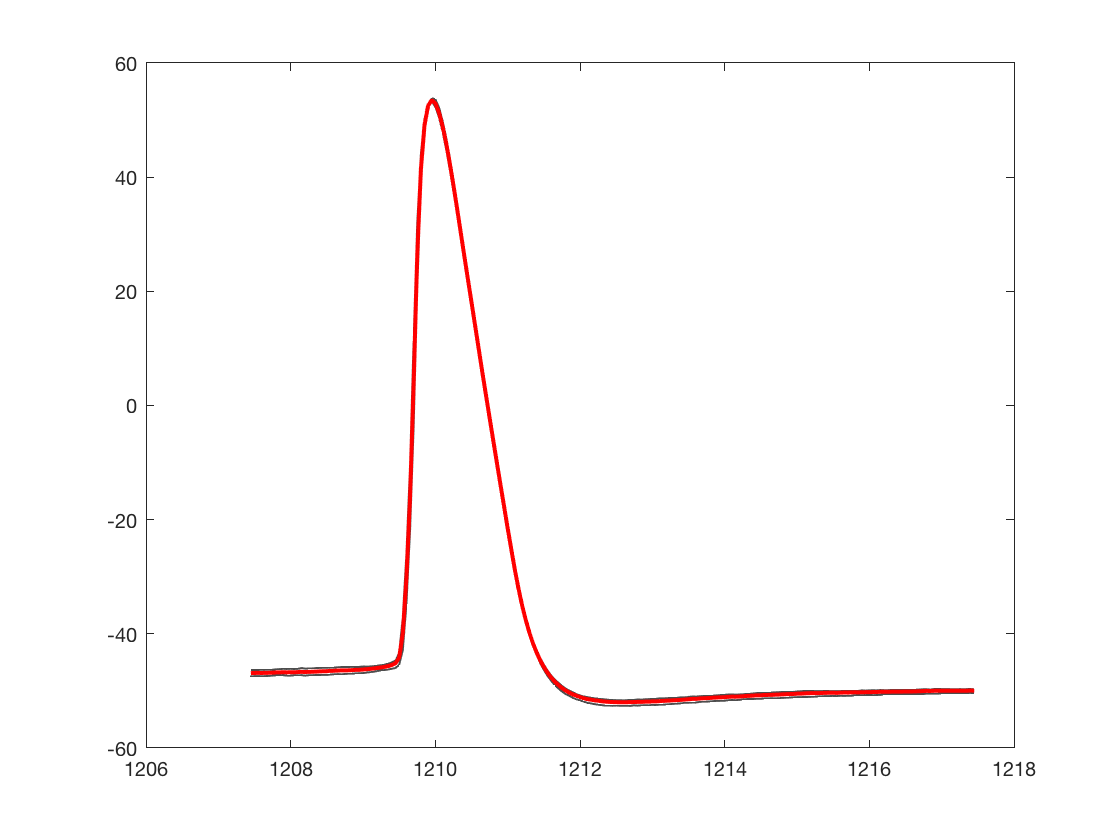

% plot all three spikes and phase-planes with averaged sweeps

in_all =[in_pp; in_pp_2; in_pp_3];
figure;
plot(t_pp,in_all,'LineWidth',1,'Color',[0.3 0.3 0.3]);
hold on
in_mean = mean(in_all);
plot(t_pp,in_mean,'LineWidth',2,'Color','r');

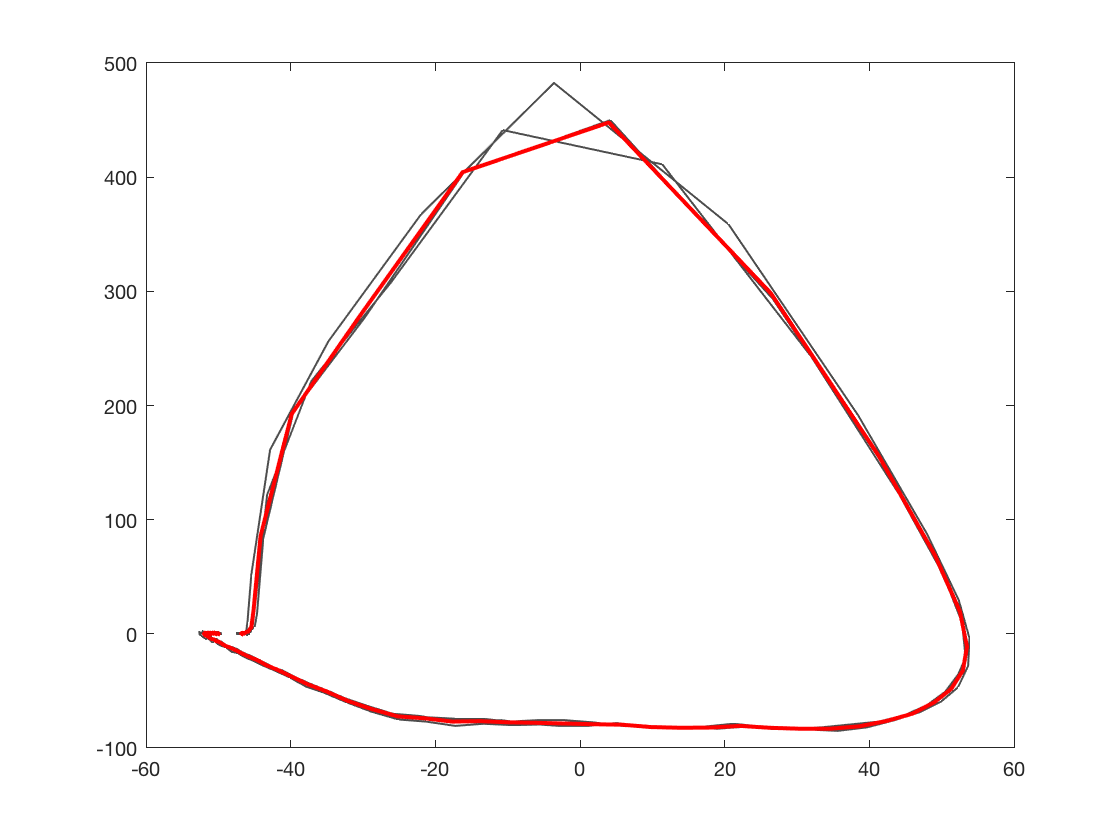



in_d_all =[in_pp_d; in_pp_d_2; in_pp_d_3];
in_d_mean = mean(in_d_all);
figure;
plot(in_pp,in_pp_d,'LineWidth',1,'Color',[0.3 0.3 0.3])
hold on
plot(in_pp_2,in_pp_d_2,'LineWidth',1,'Color',[0.3 0.3 0.3])
plot(in_pp_3,in_pp_d_3,'LineWidth',1,'Color',[0.3 0.3 0.3])
plot(in_mean,in_d_mean,'LineWidth',2,'Color','r');

## output values!



spike_count = [length(PKS) length(PKS_2) length(PKS_3)]

spike_count =     14    14    14


spikeamp_all = [spikeamp spikeamp_2 spikeamp_3]

spikeamp_all =    99.8137   98.3137   98.5325


halfwidth_all = [halfwidth halfwidth_2 halfwidth_3]

halfwidth_all =     0.9673    0.9697    0.9787


maxrate = [max(in_pp_d) max(in_pp_d_2) max(in_pp_d_3)]

maxrate =   482.5000  450.0000  441.2500


minrate = [min(in_pp_d) min(in_pp_d_2) min(in_pp_d_3)]

minrate =   -85.0000  -83.1250  -83.1250


AP_th_all = [AP_th AP_th_2 AP_th_3]

AP_th_all =   -45.9700  -44.9700  -45.2200


rheobase_all = [rheobase rheobase_2 rheobase_3]

rheobase_all =   591.2083  585.7917  592.4583


afterhyp_all = [afterhyp afterhyp_2 afterhyp_3]

afterhyp_all =    -6.6550   -6.7800   -6.4363






a = [mean(spike_count); mean(spikeamp_all);mean(halfwidth_all) ; mean(maxrate); mean(minrate); mean(afterhyp_all); mean(AP_th_all); mean(rheobase_all)]

a =    14.0000
   98.8867
    0.9719
  457.9167
  -83.7500
   -6.6238
  -45.3867
  589.8194
